# FSK Message Generator and Debug Demodulator

- Sebastian Heide

- Alexander Innerbichler

- Elias Lermann

- Johra-Markus Singh

## Header

close all
clear
clc

### Define Signal Proberties

T_bit   = 0.1;    %[s]
Fs      = 10000;    %[Hz]
f0      = 440;     %[Hz]
f1      = 880;     %[Hz]
A       = 0.2; 
SNR     = 20;

wavFilename = 'msg.wav';

## FSK Message Loop

### Continously enter a message and send it over sound

switch questdlg('Continues Messaging?', 'Loop', 'Yes', 'No', 'No')
    case 'Yes'
        while 1==1
            msg = cell2mat(inputdlg('Enter a message to be sent', 'Message', [1 50]));
            if num2str(msg) == ""
                return
            end
                u = generateFSK(msg, T_bit, Fs, f0, f1, A);
                u = [generateFSK(0b10101010, T_bit, Fs, f0, f1, A) u];
                u = [zeros(1, T_bit*Fs) u zeros(1, T_bit*Fs)];
                % u = awgn(u,SNR);
                sound(u, Fs);
        end
end

## FSK Generator

### Fetch message from input dialog

msg = cell2mat(inputdlg('Enter a message to be sent', 'Message', [1 50]));

### Generate FSK-Signal

u = generateFSK(msg, T_bit, Fs, f0, f1, A);

Generate preamble

u = [generateFSK(0b10101010, T_bit, Fs, f0, f1, A) u];

Add zeros to start and end of Signal for T_bit amount of time

u = [zeros(1, T_bit*Fs) u zeros(1, T_bit*Fs)];

#### Add Noise

switch questdlg('Add noise to signal?', 'Noise', 'Yes', 'No', 'Yes')
    case 'Yes'
        u = awgn(u,SNR);
end

### Plot Signal

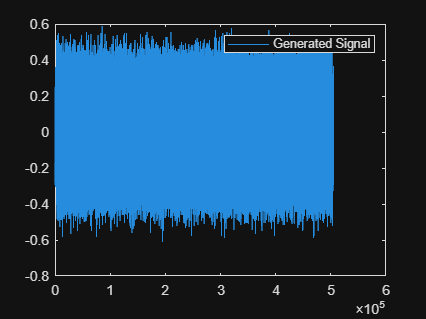

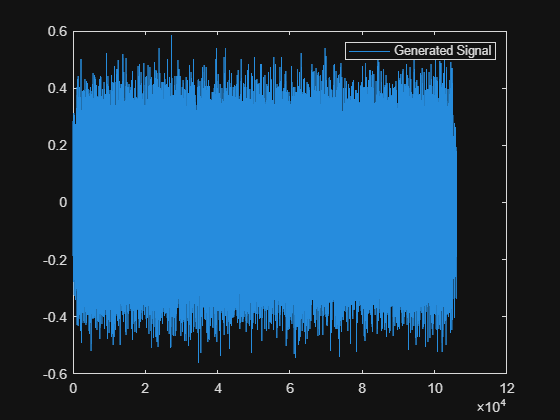

plot(u)
legend('Generated Signal');

### Save FSK to WAV and output sound

audiowrite(wavFilename, u, Fs);

switch questdlg('Output Sound?', 'Sound', 'Yes', 'No', 'No')
    case 'Yes'
        sound(u, Fs);
end

## Demodulator

switch questdlg('Demodulate Signal?', 'Demodulater', 'Yes', 'No', 'Yes')
    case 'No'
        return
end

### Read WAV

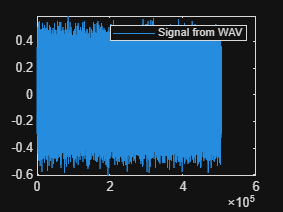

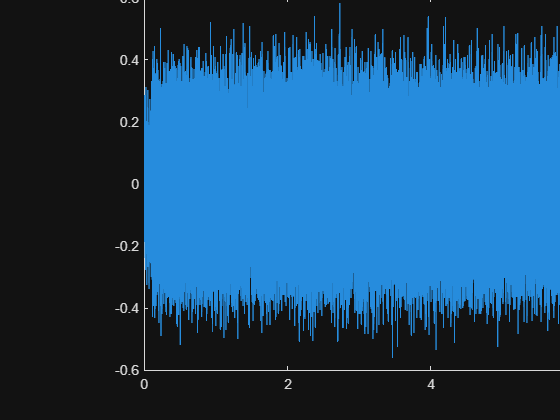

[u_read Fs] = audioread(wavFilename);

figure(name='Signal read from WAV');
plot(u_read);
legend('Signal from WAV');

### Generate filter FSK Signals

generateFSK() does padding to only output a complete Byte (sets zeros infront of data if necessary)

Also k is going backwards to achieve flipped signal for matched filtering

k = (T_bit*Fs - 1):-1:0;
t = k/Fs;
s_0 = A*sin(2*pi*f0*t);
s_1 = A*sin(2*pi*f1*t);

### Demodulate Signal using Matlab convolution and complete signal

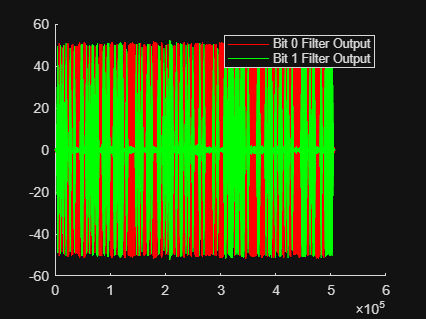

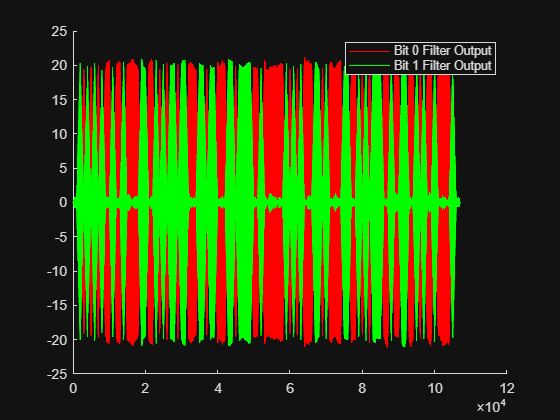

y0 = conv(u_read, s_0);
y1 = conv(u_read, s_1);

figure(name='Demodulated with complete signal');
hold on
plot(y0, 'r');
plot(y1, 'g');
legend('Bit 0 Filter Output', 'Bit 1 Filter Output');
hold off

### Demodulate Signal like on STM32

using FSK_filter class, defined in FSK_filter.m

SCHWELLENWERT_OBEN  = 2200;
SCHWELLENWERT_UNTEN = 2000;
idle_step_size = 10;

rx_msg = [];

f = FSK_filter(T_bit, Fs, f0, f1, A, SCHWELLENWERT_OBEN, SCHWELLENWERT_UNTEN, idle_step_size);

switch questdlg('Plot Animation?', 'Animation', 'Yes', 'No', 'No')
    case 'Yes'
        animation = 1;
    case 'No'
        animation = 0;
end
if animation
    filter_anim_fig = figure(name='Filter Animation');
    set(filter_anim_fig, 'Visible', 'on');
    hold on;
    u_animline = animatedline;
    rms0_animline = animatedline('Color','r');
    rms1_animline = animatedline('Color','b');
    legend('Transmitted Signal', 'Bit 0 Filter Output (RMS)', 'Bit 1 Filter Output (RMS)');
    hold off;
end

for i=1:1:size(u_read,1)
    % get data continuously, fill circular buffer with it (like the ADC)
    % and convolute incoming signal with filter every T_Bit (T_Bit*Fs
    % elements / calls to update) or every idle_step_size elements if transmission signal
    % is not detected yet.
    % idle_step_size speeds up the calculation up until the first bit is
    % recognized, else every call a calculation would be done
    
    f = f.update(u_read(i));

    if (f.isByteFinished)
        if f.byte == 0b10101010
            disp("Msg Start:");
        else
        % print current byte/char but also save it into a message vector
        % which gets printed at end of transmission
        rx_msg = [rx_msg char(f.byte)];
        disp(char(f.byte) + ":" + f.byte);
        end
        % byte and bit_cnt needs to reseted, sadly not possible to reset in
        % class methods (see: FSK_filter.m @line 169 hehe)
        f.byte = 0;
        f.bit_cnt = 0;
    end

    if animation
        addpoints(u_animline, i, u_read(i)*100);
        addpoints(rms0_animline, i, f.y0);
        addpoints(rms1_animline, i, f.y1);
        drawnow limitrate;
    end
end

Msg Start:


H:72
e:101
l:108
l:108
o:111
 :32
T:84
h:104
e:101
r:114
e:101
!:33
 :32
H:72
o:111
w:119
 :32
a:97
r:114
e:101
 :32
y:121
a:97
?:63


drawnow;

disp("Received Message: " + rx_msg);

Received Message: Hello There! How are ya?


## Function Definitions

### generateFSK()

function x = generateFSK(data, T_bit, Fs, f0, f1, A)
    % Function generates one signal for 0 (s_0) and one for 1 (s_1)
    % Than iterates over given data and appends either s_0 or s_1 to the
    % output wave. Not the most effective algo (heck ton of vector
    % resizing), but still fast enough

    k = 0:1:(T_bit*Fs - 1);
    t_bit = k/Fs;
    s_0 = A*sin(2*pi*f0*t_bit);
    s_1 = A*sin(2*pi*f1*t_bit);
    
    decStr = dec2bin(data, 8);

    x = [];

    for i = 1:size(decStr, 1)
        for j = 1:size(decStr, 2)
            if decStr(i, j) == '0'
                x = [x, s_0];
            else 
                x = [x, s_1];
            end
        end
    end
end